# Compute Impulse Response

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

[whaley,fs] = audioread("./data/whalesound.wav");
biir = [0.5 0.25];
aiir = [1 -0.1];
bfir = [0.2 0.5 0.2];
whalefilt = filter(biir,aiir,whaley);

## Task 1

The impulse response of an IIR filter is infinitely long, so its impulse response would be an infinitely long vector.

If you want to implement an IIR filter with convolution in MATLAB, you need to truncate the impulse response. But how do you know when to truncate it?

You can display the first `n` samples of the impulse response of a digital filter using the `impz` function.

`impz``(``b``,``a``,``n``,``fs``)`

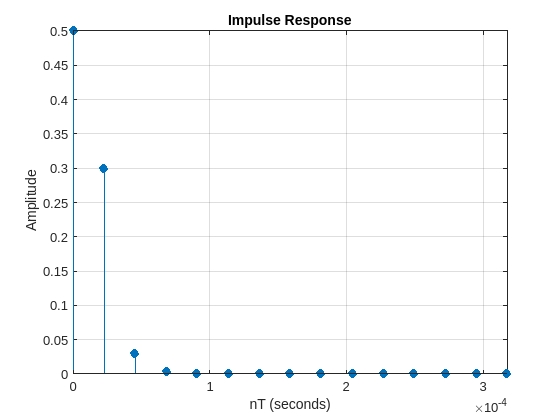

impz(biir,aiir,15,fs)
grid on

## Task 2

Even though this is an IIR filter, the impulse response settles around zero by its fifth element.

To save the impulse response to a vector, you can request two outputs from the `impz` function.

`[``h``,``t``]` `=` `impz``(``b``,``a``,``n``,``fs``)`

`h` is the impulse response and `t` is the time at each sample, in seconds.

[h,t] = impz(biir,aiir,5,fs)

h =     0.5000
    0.3000
    0.0300
    0.0030
    0.0003


t = 1.0e-04 *

         0
    0.2268
    0.4535
    0.6803
    0.9070


## Task 3

In MATLAB, you'll usually filter a signal using the `filter` function. You can perform convolution yourself with the `conv` function. The first input is the signal that you want to filter and the second input is the impulse response.

`out` `=` `conv``(``sig``,``h``)`

If you'd like to learn more about convolution, you can download the Convolution in Digital Signal Processing module from  or .

whaleconv = conv(whaley,h);

## Task 4

With FIR filters, the impulse response is the same as the coefficient vector `b`.

whaleconvfir = conv(whaley,bfir);